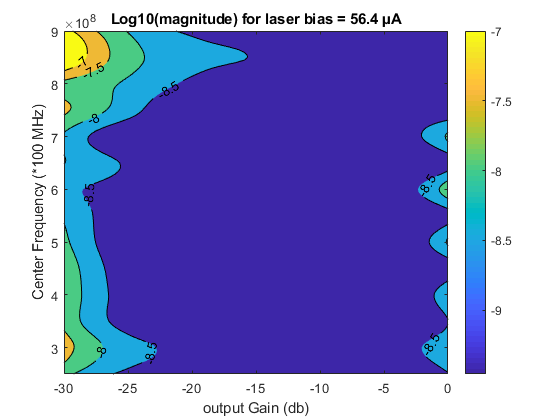

%courant bias%
courant_bias = 56.4; %(µA)%

minGain = -30; %minimum transmited power gain (in db)
maxGain =  0; %maximum transmited power gain (in db)
padGain = 5;   %measure pad for gains
numMeasurmentsGain = (abs(minGain) - abs(maxGain))/padGain;

minCarrierFrequency =  2.5e8; %minimum center frequency supported by adalm pluto (in hz)
maxCarrierFrequency =  9e8; %maximum centr frequency supported by the laser (in hz)
padCarrierFrequency =  50000e3; %pad of 10 khZ
numMeasurementsFreq = (maxCarrierFrequency-minCarrierFrequency)/padCarrierFrequency;
AverageError_function_Gain_CarrierFrequency = zeros(numMeasurementsFreq,numMeasurmentsGain);
Ber_function_Gain_CarrierFrequency = zeros(numMeasurementsFreq,numMeasurmentsGain);

x = minGain : padGain : maxGain;
y = minCarrierFrequency : padCarrierFrequency : maxCarrierFrequency;

% 0.7071 - 0.7071i
data_EVR_qpsk = [0.164360663307677,0.137363636897974,0.134961385594509,0.119176119319916,0.117049806765737,0.115730042640093,0.139887473556222;
    0.186530868181333,0.147242220528610,0.136357487301562,0.119046186415315,0.117216519995335,0.129111479364222,0.152575574007993;
    0.173103550188073,0.134380569820796,0.133192273972826,0.118016230607397,0.128149679769992,0.115043114137586,0.140957874069986;
    0.175715115045624,0.134202775018663,0.137002617944457,0.121802728183943,0.131680409481200,0.116343382172040,0.155920986610502;
    0.173556859139066,0.132382945231157,0.135526869002574,0.117823590327393,0.130768383205501,0.115456914834262,0.131677710904949;
    0.163302783358311,0.130038300611800,0.134922454306369,0.132243902078652,0.118342851237670,0.116910981551649,0.160451797755337;
    0.156192388238070,0.129321332891593,0.121176352257876,0.117756799584953,0.116179214954587,0.115405205211931,0.135736557336444;
    0.144047058039457,0.135780995098088,0.130417875441450,0.118520321428774,0.126350581822067,0.125556083178008,0.167968767158061;
    0.158913547918041,0.139481846500379,0.132212503872147,0.117681124543152,0.128232658305209,0.115244948594453,0.133975837848953;
    0.156036953483154,0.128579290186661,0.131375121162702,0.128830844680025,0.126858754353014,0.126113871635428,0.161115319437425;
    0.181438840886669,0.148289289473351,0.122984583468513,0.132712609345584,0.130120865639732,0.128832329256346,0.130445219818654;
    0.173650458078026,0.155701208759038,0.137114758160557,0.119940378302791,0.118416027756234,0.117600531780999,0.136769476578598;
    0.228908236711602,0.165596334107580,0.148760003505808,0.139428678240334,0.117911583094303,0.116511272837586,0.131927046654047;
    0.209231426686911,0.157430454943830,0.137084248053016,0.121193687686470,0.118395206297617,0.117389418693670,0.126844725420923];

data_ber_qpsk = [0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0];


figure (1)
z1 = 10*log10(data_EVR_qpsk);
%z1(isinf(-z1)) = -5.1;
[Xq,Yq] = ndgrid(minGain:(padGain/10):maxGain,...
    minCarrierFrequency:(padCarrierFrequency/10):maxCarrierFrequency);
% Vq = F(Xq,Yq);
Vq = interp2(x,y,z1,Xq,Yq,'cubic');
contourf(Xq,Yq,Vq,[-11 -10 -9.5 -8.5 -8 -7.5 -7 -6 -5 0 ],'ShowText','on');
colorbar 
title('Log10(magnitude) for laser bias = 56.4 µA');
xlabel('output Gain (db)');
ylabel('Center Frequency (*100 MHz)');

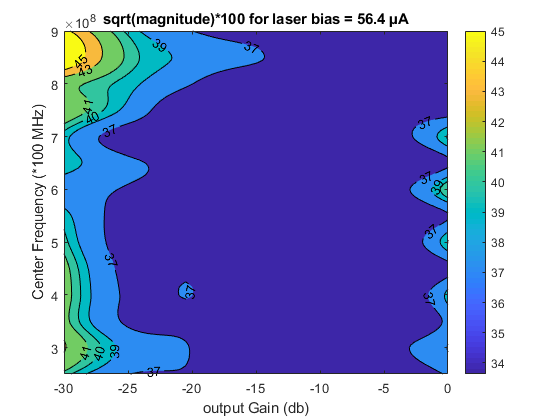


figure (2)
z2 = sqrt(data_EVR_qpsk)*100;
%z1(isinf(-z1)) = -5.1;
[Xq,Yq] = ndgrid(minGain:(padGain/10):maxGain,...
    minCarrierFrequency:(padCarrierFrequency/10):maxCarrierFrequency);
% Vq = F(Xq,Yq);
Vq = interp2(x,y,z2,Xq,Yq,'cubic');
contourf(Xq,Yq,Vq,[45 43 41 40 39 37 33],'ShowText','on');
colorbar 
title('sqrt(magnitude)*100 for laser bias = 56.4 µA');
xlabel('output Gain (db)');
ylabel('Center Frequency (*100 MHz)');